# Control de sistemas biológicos TP N°1 PROBLEMA 2 (dado)

A continuación se resuelve el ejercicio 3 de la práctica N°1 (producción bacterial de bioplástico).

El modelo a controlar es el siguiente:

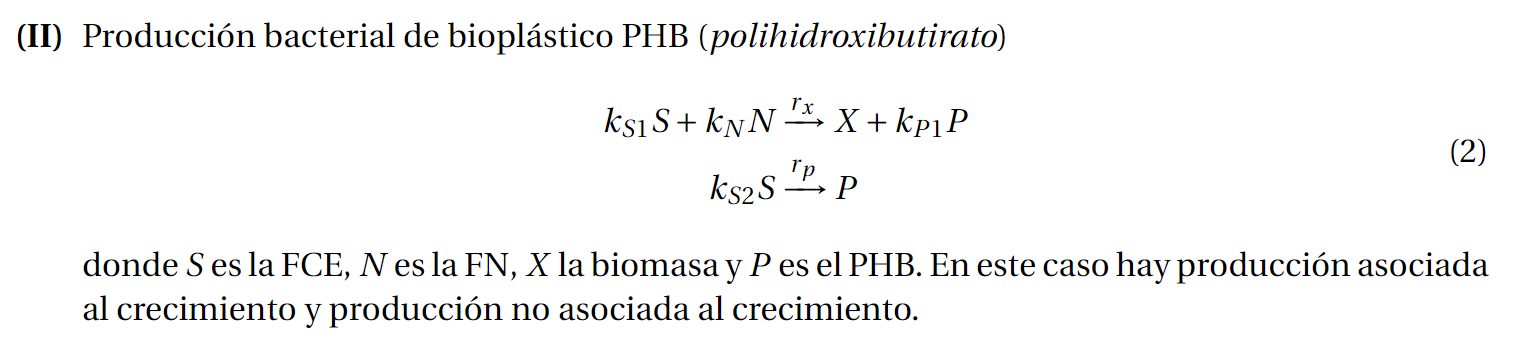

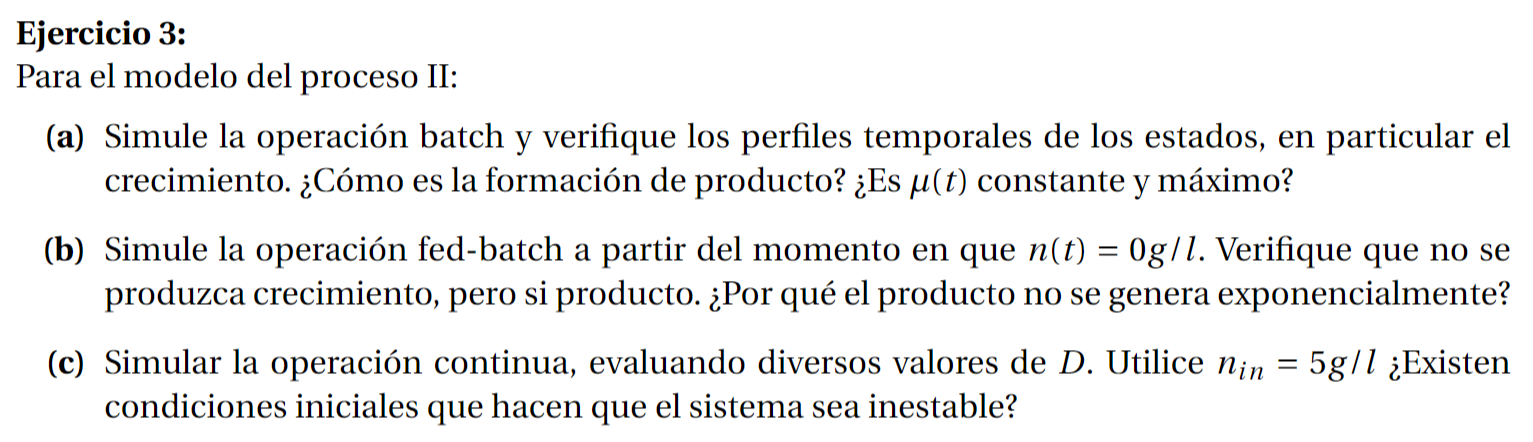

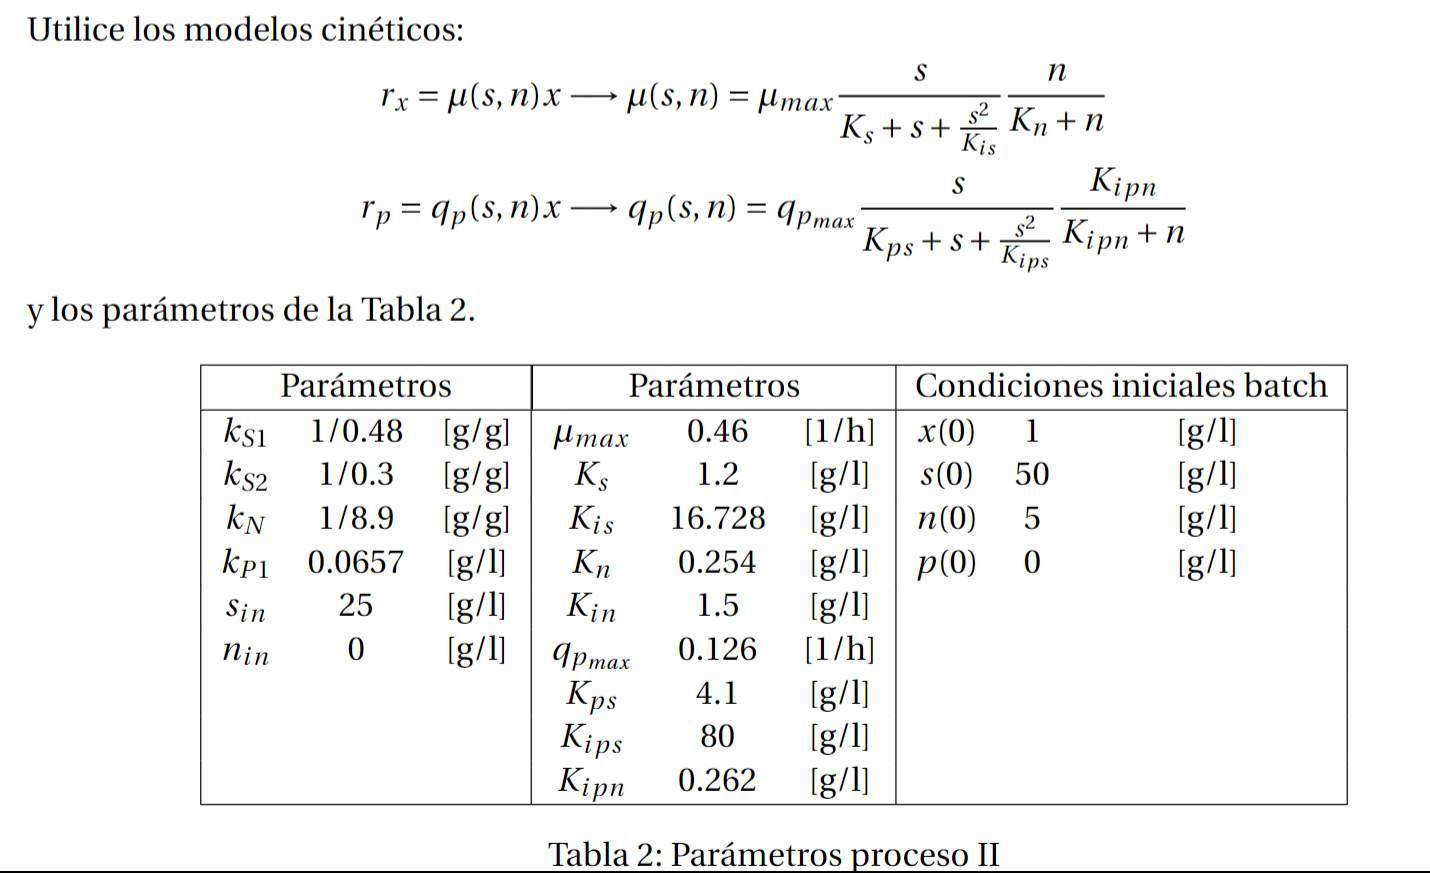

## Preguntas

- ¿Cómo funciona D?

- Sacar ec diff?


$$\begin{array}{l}
\dot{V} =F_s \\
D_s =\frac{F_s }{V}
\end{array}$$


clear all; close all; clc;

Defino los parámetros del modelo para un batch con modelo de Monod/Haldane

% Datos dados
ks1=1/0.48;
ks2=1/0.3;
kn=1/8.9;
kp1=0.0657;
s_in=25;
n_in=0;
mu_max=0.46;
Ks=1.2;
Kis=16.728;
Kn=0.254;
Kin=1.5;
qp_max=0.126;
Kps=4.1;
Kips=80;
Kipn=0.262;
p0=0;
v0=10; % Cantidad de masa inicial (en gramos)
% s0=50;
% x0=1;
% n0=5;
% Ds=0.00;
% Dn=0.0;

% IMPORTANTE: Definio una estructura que contiene todas las combinaciones
% de valores que voy a ir cambiando en las diferentes simulaciones
% Ajusto los datos para la producción de biomasa
sim_data{1}.x0=5; % Valores inciales de biomasa
sim_data{1}.Ds=0; % Valores de dilución (igual terminan siendo la misma)
sim_data{1}.Dn=0; % Valores de dilución (igual terminan siendo la misma)
sim_data{1}.n0=30; % Concentraciones inciales de nitrogeno
sim_data{1}.s0=80; % Concentraciones inciales de sustrato
% Ajusto datos para la produccion de plástico
sim_data{2}.x0=31; % Valores inciales de biomasa
sim_data{2}.Ds=0.1; % Valores de dilución (igual terminan siendo la misma)
sim_data{2}.Dn=0; % Valores de dilución (igual terminan siendo la misma)
sim_data{2}.n0=0; % Concentraciones inciales de nitrogeno
sim_data{2}.s0=0; % Concentraciones inciales de sustrato    

% Simulación
sim_results = cell(length(sim_data), 1);
for i=1:length(sim_data)
    
    x0=sim_data{i}.x0;
    n0=sim_data{i}.n0;
    s0=sim_data{i}.s0;
    F=[0;0;0;0];
    Q=[0;0;0;0];
    Ds=sim_data{i}.Ds;
    Dn=sim_data{i}.Dn;

    % Parámetros para el modelo
    modelParameters.rx_params.max=mu_max;
    modelParameters.rx_params.k1=Ks;
    modelParameters.rx_params.k2=Kis;
    modelParameters.rx_params.k3=Kn;
    
    modelParameters.rp_params.max=qp_max;
    modelParameters.rp_params.k1=Kps;
    modelParameters.rp_params.k2=Kips;
    modelParameters.rp_params.k3=Kipn;
    
    modelParameters.Kipn=Kipn;
    modelParameters.K=[1,0;-ks1,-ks2;-kn,0;kp1,1];
    
    % Definimos entradas y condiciones iniciales
    xi_in=[0,0; s_in,0; 0,n_in; 0,0];
    D=Ds;
    xi0=[x0;s0;n0;p0];
    
    simConfig.StopTime = "21";
    simConfig.Solver = 'ode1';
    simConfig.FixedStep = '0.01';
    sim_out = sim('TP1\TP1EJ3', simConfig);
    
    sim_results{i}.time = sim_out.tout;
    sim_results{i}.biomass = reshape(sim_out.x.Data, size(sim_results{i}.time));
    sim_results{i}.sustrate = reshape(sim_out.s.Data, size(sim_results{i}.time));
    sim_results{i}.nitrogen = reshape(sim_out.n.Data, size(sim_results{i}.time));
    sim_results{i}.plastic = reshape(sim_out.p.Data, size(sim_results{i}.time));
    sim_results{i}.rx = reshape(sim_out.rx.Data, size(sim_results{i}.time));
    sim_results{i}.rp = reshape(sim_out.rp.Data, size(sim_results{i}.time));
    sim_results{i}.v = reshape(sim_out.v.Data, size(sim_results{i}.time));
    sim_results{i}.sim_data = sim_data{i};

end

states =
    0.3934
   -0.8284
   -0.0442
    0.0285

states =
    0.3937
   -0.8292
   -0.0442
    0.0285

states =
    0.3941
   -0.8299
   -0.0443
    0.0286

states =
    0.3944
   -0.8306
   -0.0443
    0.0286

states =
    0.3948
   -0.8313
   -0.0444
    0.0286

states =
    0.3951
   -0.8321
   -0.0444
    0.0286

states =
    0.3955
   -0.8328
   -0.0444
    0.0287

states =
    0.3958
   -0.8335
   -0.0445
    0.0287

states =
    0.3962
   -0.8342
   -0.0445
    0.0287

states =
    0.3965
   -0.8350
   -0.0446
    0.0287

states =
    0.3968
   -0.8357
   -0.0446
    0.0288

states =
    0.3972
   -0.8364
   -0.0446
    0.0288

states =
    0.3975
   -0.8372
   -0.0447
    0.0288

states =
    0.3979
   -0.8379
   -0.0447
    0.0288

states =
    0.3982
   -0.8386
   -0.0447
    0.0289

states =
    0.3986
   -0.8394
   -0.0448
    0.0289

states =
    0.3989
   -0.8401
   -0.0448
    0.0289

states =
    0.3993
   -0.8408
   -0.0449
    0.0289

states =
    0.3996
   -0.84

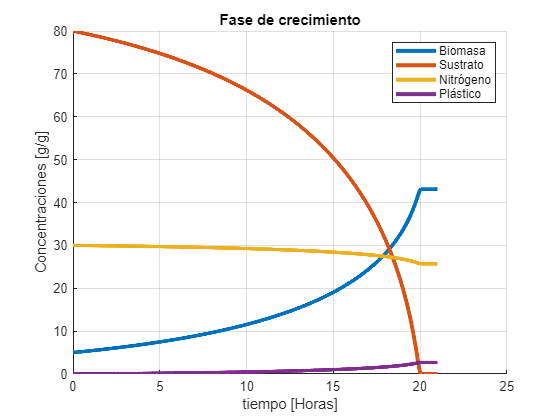

    
% Se grafica
figure();
hold on; grid on;
title('Fase de crecimiento');
xlabel('tiempo [Horas]');
ylabel('Concentraciones [g/g]');
i=1;
plot(sim_results{i}.time, sim_results{i}.biomass, 'LineWidth', 3);
plot(sim_results{i}.time, sim_results{i}.sustrate, 'LineWidth', 3);
plot(sim_results{i}.time, sim_results{i}.nitrogen, 'LineWidth', 3);
plot(sim_results{i}.time, sim_results{i}.plastic, 'LineWidth', 3);
legend('Biomasa', 'Sustrato', 'Nitrógeno', 'Plástico');

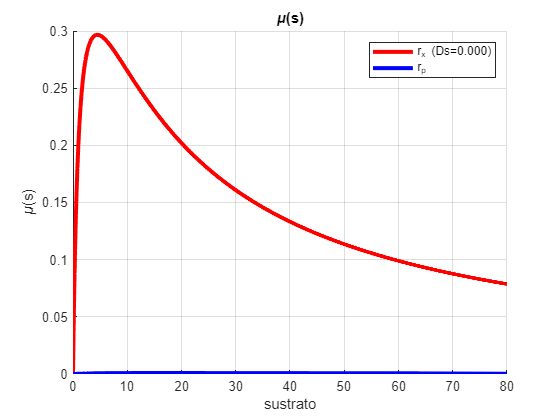

figure();
hold on; grid on;
title('\mu(s)');
xlabel('sustrato');
ylabel('\mu(s)');

plot(sim_results{i}.sustrate, sim_results{i}.rx, 'r', 'LineWidth', 3);
plot(sim_results{i}.sustrate, sim_results{i}.rp, 'b', 'LineWidth', 3);
legend(sprintf('r_x (Ds=%.3f)', sim_results{i}.sim_data.Ds), 'r_p');

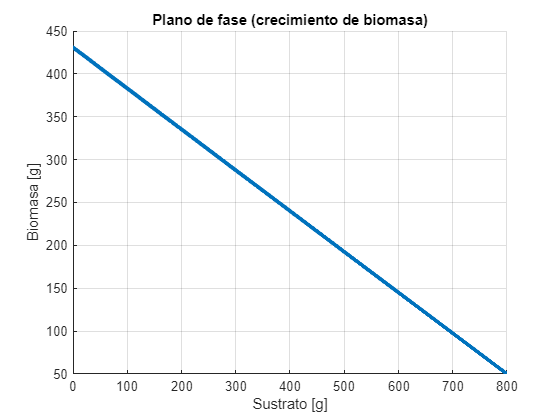

figure();
hold on; grid on;
title('Plano de fase (crecimiento de biomasa)');
xlabel('Sustrato [g]');
ylabel('Biomasa [g]');
i=1;
plot(sim_results{i}.sustrate.*sim_results{i}.v, sim_results{i}.biomass.*sim_results{i}.v, 'LineWidth', 3);

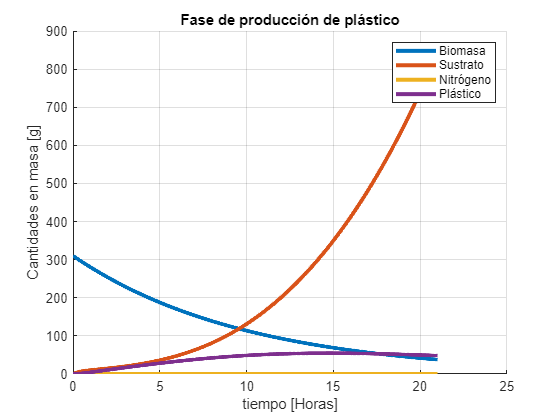


figure();
hold on; grid on;
title('Fase de producción de plástico');
xlabel('tiempo [Horas]');
ylabel('Cantidades en masa [g]');
i=2;
plot(sim_results{i}.time, sim_results{i}.biomass.*sim_results{i}.v, 'LineWidth', 3);
plot(sim_results{i}.time, sim_results{i}.sustrate.*sim_results{i}.v, 'LineWidth', 3);
plot(sim_results{i}.time, sim_results{i}.nitrogen.*sim_results{i}.v, 'LineWidth', 3);
plot(sim_results{i}.time, sim_results{i}.plastic.*sim_results{i}.v, 'LineWidth', 3);
legend('Biomasa', 'Sustrato', 'Nitrógeno', 'Plástico');

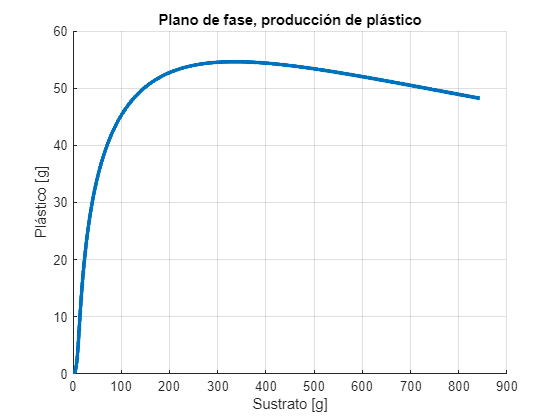

figure();
hold on; grid on;
title('Plano de fase, producción de plástico');
xlabel('Sustrato [g]');
ylabel('Plástico [g]');
i=2;
plot(sim_results{i}.sustrate.*sim_results{i}.v, sim_results{i}.plastic.*sim_results{i}.v, 'LineWidth', 3);

## Fed-Batch con alimentación exponencial de sustrato

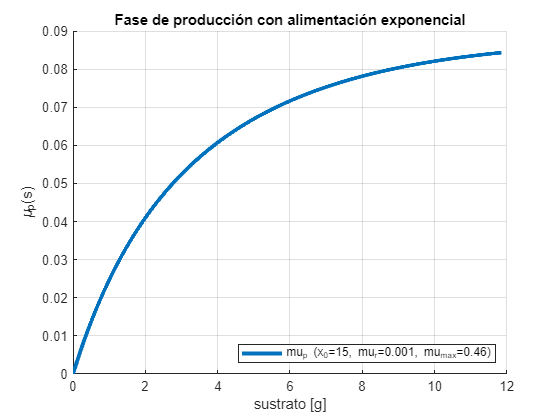

% Datos dados
ks1=1/0.48;
ks2=1/0.3;
kn=1/8.9;
kp1=0.0657;
s_in=25;
n_in=0;
mu_max=0.46;
Ks=1.2;
Kis=16.728;
Kn=0.254;
Kin=1.5;
qp_max=0.126;
Kps=4.1;
Kips=80;
Kipn=0.262;
p0=0;
v0=10; % Cantidad de masa inicial (en gramos)
n0=0;
s0=0;
F=[0;0;0;0];
Q=[0;0;0;0];
Dn=0;

clear sim_data; clear modelParameters; clear sim_results;

sim_data{1}.x0=15;
sim_data{1}.mur0=0.001;

% sim_data{2}.x0=15;
% sim_data{2}.mur0=0.05;
% 
% sim_data{3}.x0=15;
% sim_data{3}.mur0=0.01;
% 
% sim_data{4}.x0=30;
% sim_data{4}.mur0=0.09;
% 
% sim_data{5}.x0=30;
% sim_data{5}.mur0=0.01;

% Simulación
sim_results = cell(length(sim_data), 1);
for i=1:length(sim_data)
    
    % Parámetros que van cambiando
    mur0=0.05;
    x0=sim_data{i}.x0;
   
    % Parámetros para el modelo
    modelParameters.rx_params.max=mu_max;
    modelParameters.rx_params.k1=Ks;
    modelParameters.rx_params.k2=Kis;
    modelParameters.rx_params.k3=Kn;
    
    modelParameters.rp_params.max=qp_max;
    modelParameters.rp_params.k1=Kps;
    modelParameters.rp_params.k2=Kips;
    modelParameters.rp_params.k3=Kipn;
    
    modelParameters.Kipn=Kipn;
    modelParameters.K=[1,0;-ks1,-ks2;-kn,0;kp1,1];
    
    % Definimos entradas y condiciones iniciales
    xi_in=[0,0; s_in,0; 0,n_in; 0,0];
    xi0=[x0;s0;n0;p0];
    
    simConfig.StopTime = "30";
    simConfig.Solver = 'ode1';
    simConfig.FixedStep = '0.01';
    sim_out = sim('TP1\TP1EJ3_2', simConfig);
    
    sim_results{i}.time = sim_out.tout;
    sim_results{i}.biomass = reshape(sim_out.x.Data, size(sim_results{i}.time));
    sim_results{i}.sustrate = reshape(sim_out.s.Data, size(sim_results{i}.time));
    sim_results{i}.nitrogen = reshape(sim_out.n.Data, size(sim_results{i}.time));
    sim_results{i}.plastic = reshape(sim_out.p.Data, size(sim_results{i}.time));
    sim_results{i}.rx = reshape(sim_out.rx.Data, size(sim_results{i}.time));
    sim_results{i}.rp = reshape(sim_out.rp.Data, size(sim_results{i}.time));
    sim_results{i}.v = reshape(sim_out.v.Data, size(sim_results{i}.time));
    sim_results{i}.Ds = reshape(sim_out.Ds.Data, size(sim_results{i}.time));
    sim_results{i}.sim_data = sim_data{i};

end
    
% Se grafica
figure();
hold on; grid on;
title('Fase de producción con alimentación exponencial');
xlabel('sustrato [g]');
ylabel('\mu_p(s)');
% ylim([0 10])
legends=cell(1, length(sim_results)); legend_counter=1;
for i=1:length(sim_results)
    plot(sim_results{i}.sustrate, sim_results{i}.rp, 'LineWidth', 3);
    legends{1,legend_counter}=sprintf('mu_p (x_0=%d, mu_r=%.3f, mu_{max}=%.2f)', sim_results{i}.sim_data.x0, sim_results{i}.sim_data.mur0, mu_max);
    legend_counter=legend_counter+1;
end
legend(legends, 'Location','southeast');

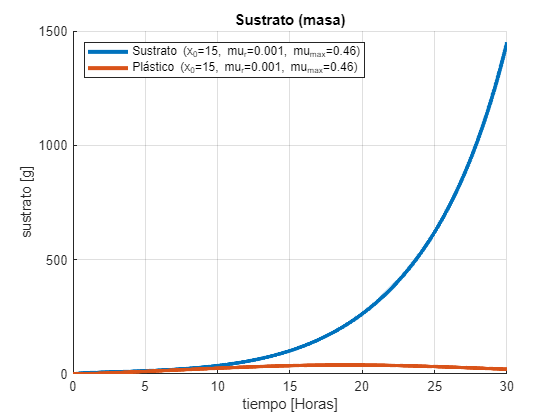

figure();
hold on; grid on;
title('Sustrato (masa)');
xlabel('tiempo [Horas]');
ylabel('sustrato [g]');
% ylim([0 10])
legends=cell(1, length(sim_results)*2); legend_counter=1;
for i=1:length(sim_results)
    plot(sim_results{i}.time, sim_results{i}.sustrate.*sim_results{i}.v, 'LineWidth', 3);
    plot(sim_results{i}.time, sim_results{i}.plastic.*sim_results{i}.v, 'LineWidth', 3);
    legends{1,legend_counter}=sprintf('Sustrato (x_0=%d, mu_r=%.3f, mu_{max}=%.2f)', sim_results{i}.sim_data.x0, sim_results{i}.sim_data.mur0, mu_max);
    legends{1,legend_counter+1}=sprintf('Plástico (x_0=%d, mu_r=%.3f, mu_{max}=%.2f)', sim_results{i}.sim_data.x0, sim_results{i}.sim_data.mur0, mu_max);
    legend_counter=legend_counter+2;
end
legend(legends, 'Location','northwest');

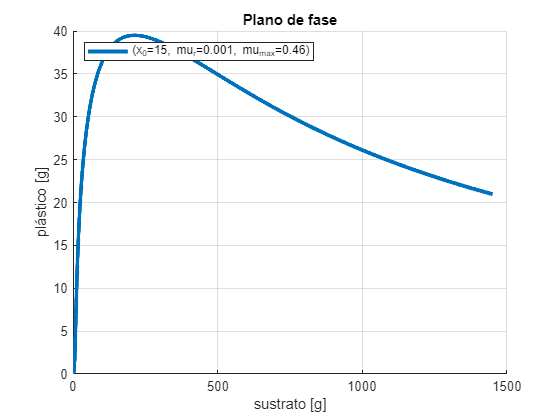

figure();
hold on; grid on;
title('Plano de fase');
ylabel('plástico [g]');
xlabel('sustrato [g]');
% ylim([0 10])
legends=cell(1, length(sim_results)); legend_counter=1;
for i=1:length(sim_results)
    plot(sim_results{i}.sustrate.*sim_results{i}.v, sim_results{i}.plastic.*sim_results{i}.v, 'LineWidth', 3);
    legends{1,legend_counter}=sprintf('(x_0=%d, mu_r=%.3f, mu_{max}=%.2f)', sim_results{i}.sim_data.x0, sim_results{i}.sim_data.mur0, mu_max);
    legend_counter=legend_counter+1;
end
legend(legends, 'Location','northwest');